## Implement Steepest Descent on the function $f(x_1, x_2) = 9x_1^2 + x_2^2 - 3x_1x_2 + 15x_1 - x_2 + 5$ to find a stationary point.

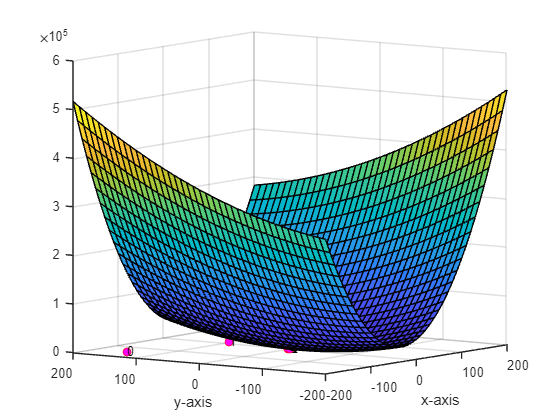

close all

epsilon = 0.01;
x0 = [-150 150];

[x1,x2] = meshgrid(-200:10:200,-200:10:200);

myFunc = 9* x1.^2 + x2.^2 - 3* x1 .* x2 + 15 * x1 - x2 + 5;

surf(x1, x2, myFunc);

xlabel('x-axis')
ylabel('y-axis')

hold on
plot(x0(1), x0(2),'o r', 'MarkerFaceColor', 'm')
text(x0(1), x0(2), int2str(0));

k = 0;
xk = x0;

while true
    
    dk = [-(18 * xk(1) - 3 * xk(2) + 15) -(-3 * xk(1) + 2 * xk(2) - 1)];
    
    lambda = Bisection(xk, dk);
    
    xk = xk + lambda * dk;
    
    k = k+ 1;
    
    plot(xk(1), xk(2),'o r', 'MarkerFaceColor', 'm')
    text(xk(1), xk(2), int2str(k));
    
    if(norm(dk) < epsilon)
        break
    end
end


xk

xk =    -1.0001   -0.9999


function lambda = Bisection(xk, dk)
    epsilon = 0.001;
    a = -100;
    b = 100;
    
    while (b - a) > epsilon
        lambda = (a + b) / 2;
        if evalLambdaFunc(lambda, xk, dk) >= evalLambdaFunc(lambda + epsilon, xk, dk)
            a = lambda;
        else b = lambda;
        end
    end
    lambda = (a + b) / 2;
end

function evalFunc = evalLambdaFunc(lambda, xk, dk)    
    x1 = xk(1) + lambda * dk(1);
    x2 = xk(2) + lambda * dk(2);
    
    evalFunc = 9* x1.^2 + x2.^2 - 3* x1 .* x2 + 15 * x1 - x2 + 5; 
end